clear; clf; close all;

wpts = [
        0  pi pi/3;
        0 pi/2 pi/5;
        pi 0 pi/3;
        ];
tpts = 1:3; tvec = 1:0.1:3;

[q, qd, qdd, pp] = quinticpolytraj(wpts, tpts, tvec);
C = pp.coefs;

T = zeros(6, 1);
thetaT = zeros(length(tvec), size(C,1), 1);

for i=1:length(tvec)
    t=tvec(i);
    T = [1 t t^2 t^3 t^4 t^5]';
    
    thetaT(i,:,:) = C*T;
end

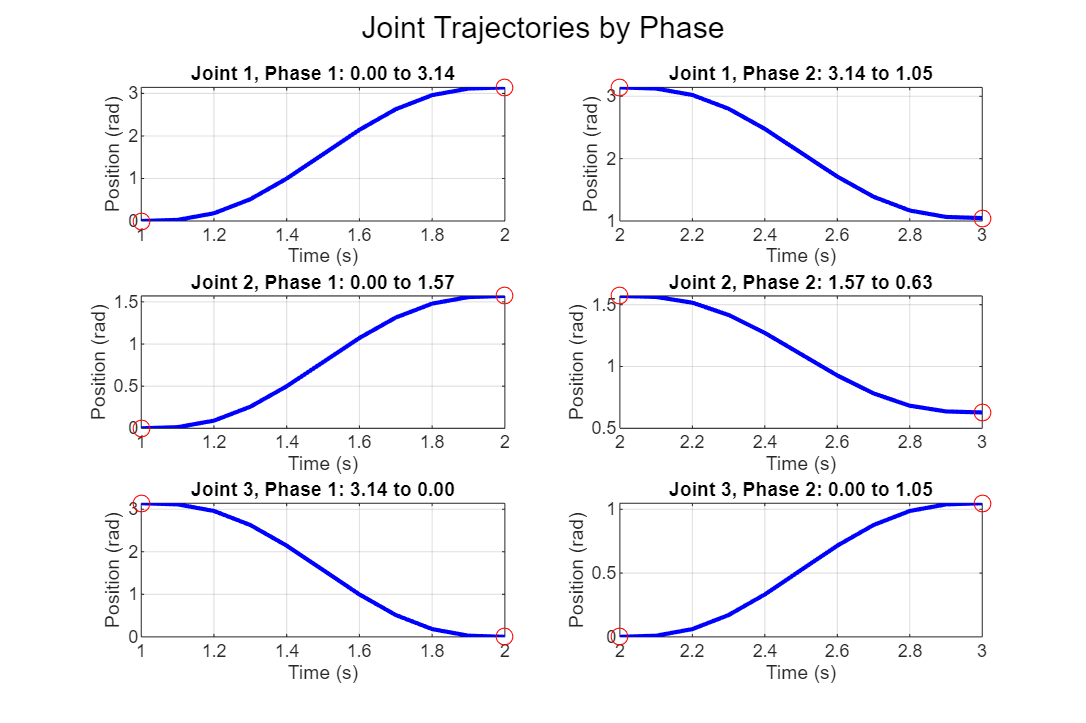

% Assuming all your previous code is executed and variables are available
n_joints = size(wpts, 1);    % Number of joints (2)
n_phases = size(wpts, 2) - 1; % Number of phases (2)

figure('Position', [100, 100, 900, 600]);

% Define phase boundaries from tpts
phase_bounds = tpts;

% Loop through joints and phases
for joint = 1:n_joints
    for phase = 1:n_phases
        % Calculate subplot index
        subplot_idx = (joint-1)*n_phases + phase;
        
        % Create subplot
        subplot(n_joints, n_phases, subplot_idx);
        
        % Define the time range for this phase
        t_phase_start = phase_bounds(phase);
        t_phase_end = phase_bounds(phase+1);
        
        % Find indices in tvec that fall within this phase
        phase_indices = find(tvec >= t_phase_start & tvec <= t_phase_end);
        
        % Plot position trajectory for this joint and phase
        plot(tvec(phase_indices), q(joint, phase_indices), 'b-', 'LineWidth', 2);
        
        % Add waypoints as markers
        hold on;
        plot([t_phase_start, t_phase_end], [wpts(joint, phase), wpts(joint, phase+1)], 'ro', 'MarkerSize', 8);
        
        % Add title and labels
        title(sprintf('Joint %d, Phase %d: %.2f to %.2f', joint, phase, wpts(joint, phase), wpts(joint, phase+1)));
        xlabel('Time (s)');
        ylabel('Position (rad)');
        grid on;
        
        % Optional: You can also plot velocity and acceleration
        % plot(tvec(phase_indices), qd(joint, phase_indices), 'g--');
        % plot(tvec(phase_indices), qdd(joint, phase_indices), 'r:');
    end
end

% Add a common title
sgtitle('Joint Trajectories by Phase');